# EE 521 Power System Analysis and EE 523 Power System Stability and Control Algorithms

### Preamble and Control Inputs

tic;
addpath functions\
systemName = "ieee11-caseThree-"

systemName = "ieee11-caseThree-"

powerFlowMethod =  "Fast Decoupled NRPF" 

powerFlowMethod = "Fast Decoupled NRPF"

useSparseDSA = false;
includeOPFScenarios = false;
showOPFFormulae = false;
showOPFValues = false;
numIterations = 50; %I don't wait for the system to converge, 
printPowerFlowConvergenceMessages = false;
% neither do I care if the system converges earlier.
toleranceLimit = 1e-3; %mean of absolute values of 
% corrections should be less than this for convergence to be achieved.
displayRawData = true;
displayYBus = true;
displayTables = true; %show busData, branchData, ybus, 
% basically data structures which are not the final output.
printJacobians = true  ; %Print Jacobians during NRPF iterations? Does not work if displayTables is off.
printMismatches = false; %Print Mismatches during NRPF iterations? Does not work if displayTables is off.
printCorrections = false;
disableTaps = false; %Disable Tap-changers when commputing YBus?
showPlots = true;
displayResults = true;
reducedBranchColumnsCDFReading = true; 
showImages = true; %might add iteration specific images later. 
verboseCDFReading = false; %Will give a verbose output when reading CDF files.
MVAb = 100; %Currently the same for all systems in database.

folder_rawData = "rawData/"; %location of CDF .txt file for the system
file_rawData = strcat(folder_rawData, systemName, "cdf.txt"); %Exact location of CDF .txt file for the system
folder_processedData = "processedData/";
% Should configure it to be read from the CDF file later.
latex_interpreter %for LaTeX typesetting in plots

### Read CDF file and store the data in neat MATLAB `tables: busData `and `branchData`.

[busData, branchData, N, numBranch] = ...
    readCDF(file_rawData, reducedBranchColumnsCDFReading, verboseCDFReading);
if displayTables && displayRawData
    displayRawDataAsTables(busData, branchData, N, numBranch);
end

busData = 11×18 table
    bus       busName        loadFlowArea    lossZone    busType    vFinal    deltaFinal     PL     QL     PG      QG      kVBase    Vset    Qmax    Qmin    G    B    remoteControlledBusNumber
    ___    ______________    ____________    ________    _______    ______    __________    ____    ___    ___    _____    ______    ____    ____    ____    _    _    _______________

branchData = 10×15 table
    i     j     loadFlowArea    lossZone    ckt    type       R          X          B       MVA1    MVA2    MVA3    controlBusNumber    side    a
    __    __    ____________    ________    ___    ____    _______    _______    _______    ____    ____    ____    ________________    ____    _

     1     5         1             1         1      0            0    0.01667          0     0       0       0             0             0      0
     2     6         1    

N = 11

numBranch = 10

### Extract $Y_{Bus}$,  Adjacency List $E$ from the `branchData table.`

if useSparseDSA
    [nnzYBus, NYBus] = makeSparseYBus(busData, branchData, displayTables, displayYBus); %#ok
else
    [ybus, BMatrix, ~, ~, ~, E] = ybusGenerator(busData, branchData);
    ybusTable = array2table(ybus, VariableNames=[string(1:N)], RowNames=[string(1:N)]);

end

if ~useSparseDSA && displayTables && displayYBus
    display(ybusTable);
end

ybusTable = 11×11 table
              1            2            3            4               5                  6                  7                  8                  9                 10                 11       
          _________    _________    _________    _________    _______________    _______________    _______________    _______________    _______________    _______________    _______________

    1     0-59.988i    0+0i         0+0i         0+0i               0+59.988i          0+0i               0+0i               0+0i               0+0i               0+0i               0+0i     
    

### Run Newton Raphson Power Flow and obtain a steady state snapshot of the system variables $P_i, Q_i, V_i, \delta_i$ $\forall$ buses $i \in [1, N], i \in \mathbb{N}$

[PSpecified, QSpecified, V, delta, ...
    listOfPQBuses, listOfPVBuses, nPQ, nPV, ...
    listOfNonSlackBuses] = initializeVectors(busData, N, MVAb);

if useSparseDSA    
    doTheSparseThing(PSpecified, QSpecified, V, delta, nnzYBus, NYBus, busData); %#ok
else
    if contains(systemName, 'caseThree')
        resultsFromCaseTwo = load("processedData\ieee11-caseTwoResults");
        resultsFromCaseTwo = resultsFromCaseTwo.resultTable;
        wiggle = 0.35; %minimum 0.35 value for good result
        V = V*(1-wiggle) + wiggle*resultsFromCaseTwo.V;
        delta = delta*(1-wiggle) + wiggle*resultsFromCaseTwo.delta;
    end
    [P, Q, V, delta] = solveForPowerFlow(PSpecified, QSpecified, V, delta, ybus, BMatrix, E, N, nPQ, nPV, listOfPQBuses, listOfNonSlackBuses, numIterations, toleranceLimit, powerFlowMethod, displayTables, printJacobians, printMismatches, printPowerFlowConvergenceMessages);

    resultTable = displayPowerFlowResults(N, P, Q, V, delta, displayResults);
    if contains(systemName, 'caseTwo') && strcmp(powerFlowMethod, 'NRPF')
        save("processedData\ieee11-caseTwoResults", "resultTable");
    end
end

Iteration Number 1 Jacobian J11:


J11Table = 10×10 table
              $delta_2$    $delta_3$    $delta_4$    $delta_5$    $delta_6$    $delta_7$    $delta_8$    $delta_9$    $delta_10$    $delta_11$
              _________    _________    _________    _________    _________    _________    _________    _________    __________    __________

    $P_2$       60.399            0            0            0      -60.447            0            0            0            0             0  
    $P_3$            0       60.894            0            0            0            0            0            0            0       -60.943  
    $P_4$    

Iteration Number 1 Jacobians:


J22Table = 10×10 table
              $DeltaVByV_2$    $DeltaVByV_3$    $DeltaVByV_4$    $DeltaVByV_5$    $DeltaVByV_6$    $DeltaVByV_7$    $DeltaVByV_8$    $DeltaVByV_9$    $DeltaVByV_10$    $DeltaVByV_11$
              _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    ______________    ______________

    $Q_2$         60.775                0               0                 0           7.0016                0               0                0                 0                 0    
    $Q_3$              0            61.99            

Iteration Number 2 Jacobian J11:


J11Table = 10×10 table
              $delta_2$    $delta_3$    $delta_4$    $delta_5$    $delta_6$    $delta_7$    $delta_8$    $delta_9$    $delta_10$    $delta_11$
              _________    _________    _________    _________    _________    _________    _________    _________    __________    __________

    $P_2$       59.942            0            0           0       -60.346            0            0            0            0             0  
    $P_3$            0       61.024            0           0             0            0            0            0            0       -61.451  
    $P_4$    

Iteration Number 2 Jacobians:


J22Table = 10×10 table
              $DeltaVByV_2$    $DeltaVByV_3$    $DeltaVByV_4$    $DeltaVByV_5$    $DeltaVByV_6$    $DeltaVByV_7$    $DeltaVByV_8$    $DeltaVByV_9$    $DeltaVByV_10$    $DeltaVByV_11$
              _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    ______________    ______________

    $Q_2$         60.572                0                0                0           6.9894                0                0               0                 0                 0    
    $Q_3$              0           63.821            

Iteration Number 3 Jacobian J11:


J11Table = 10×10 table
              $delta_2$    $delta_3$    $delta_4$    $delta_5$    $delta_6$    $delta_7$    $delta_8$    $delta_9$    $delta_10$    $delta_11$
              _________    _________    _________    _________    _________    _________    _________    _________    __________    __________

    $P_2$       60.236            0            0            0      -60.642            0            0            0            0             0  
    $P_3$            0       61.125            0            0            0            0            0            0            0       -61.538  
    $P_4$    

Iteration Number 3 Jacobians:


J22Table = 10×10 table
              $DeltaVByV_2$    $DeltaVByV_3$    $DeltaVByV_4$    $DeltaVByV_5$    $DeltaVByV_6$    $DeltaVByV_7$    $DeltaVByV_8$    $DeltaVByV_9$    $DeltaVByV_10$    $DeltaVByV_11$
              _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    ______________    ______________

    $Q_2$         59.995                0                0                0           7.0019               0                0                0                 0                 0    
    $Q_3$              0           63.377            

Iteration Number 4 Jacobian J11:


J11Table = 10×10 table
              $delta_2$    $delta_3$    $delta_4$    $delta_5$    $delta_6$    $delta_7$    $delta_8$    $delta_9$    $delta_10$    $delta_11$
              _________    _________    _________    _________    _________    _________    _________    _________    __________    __________

    $P_2$       60.571            0            0            0      -60.977            0            0            0            0             0  
    $P_3$            0       61.372            0            0            0            0            0            0            0       -61.792  
    $P_4$    

Iteration Number 4 Jacobians:


J22Table = 10×10 table
              $DeltaVByV_2$    $DeltaVByV_3$    $DeltaVByV_4$    $DeltaVByV_5$    $DeltaVByV_6$    $DeltaVByV_7$    $DeltaVByV_8$    $DeltaVByV_9$    $DeltaVByV_10$    $DeltaVByV_11$
              _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    ______________    ______________

    $Q_2$         61.344                0                0                0          7.0096                 0                0               0                 0                 0    
    $Q_3$              0           63.839            

Iteration Number 5 Jacobian J11:


J11Table = 10×10 table
              $delta_2$    $delta_3$    $delta_4$    $delta_5$    $delta_6$    $delta_7$    $delta_8$    $delta_9$    $delta_10$    $delta_11$
              _________    _________    _________    _________    _________    _________    _________    _________    __________    __________

    $P_2$        60.66           0             0            0      -61.063            0            0            0            0             0  
    $P_3$            0      61.481             0            0            0            0            0            0            0         -61.9  
    $P_4$    

Iteration Number 5 Jacobians:


J22Table = 10×10 table
              $DeltaVByV_2$    $DeltaVByV_3$    $DeltaVByV_4$    $DeltaVByV_5$    $DeltaVByV_6$    $DeltaVByV_7$    $DeltaVByV_8$    $DeltaVByV_9$    $DeltaVByV_10$    $DeltaVByV_11$
              _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    ______________    ______________

    $Q_2$         60.774                0                0                0           7.0126                0               0                0                 0                 0    
    $Q_3$              0           64.059            

Iteration Number 6 Jacobian J11:


J11Table = 10×10 table
              $delta_2$    $delta_3$    $delta_4$    $delta_5$    $delta_6$    $delta_7$    $delta_8$    $delta_9$    $delta_10$    $delta_11$
              _________    _________    _________    _________    _________    _________    _________    _________    __________    __________

    $P_2$       60.785            0            0            0      -61.188            0            0            0            0             0  
    $P_3$            0       61.605            0            0            0            0            0            0            0       -62.025  
    $P_4$    

Iteration Number 6 Jacobians:


J22Table = 10×10 table
              $DeltaVByV_2$    $DeltaVByV_3$    $DeltaVByV_4$    $DeltaVByV_5$    $DeltaVByV_6$    $DeltaVByV_7$    $DeltaVByV_8$    $DeltaVByV_9$    $DeltaVByV_10$    $DeltaVByV_11$
              _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    ______________    ______________

    $Q_2$         61.628                0                0                0           7.0144                0                0               0                 0                 0    
    $Q_3$              0           64.004            

Iteration Number 7 Jacobian J11:


J11Table = 10×10 table
              $delta_2$    $delta_3$    $delta_4$    $delta_5$    $delta_6$    $delta_7$    $delta_8$    $delta_9$    $delta_10$    $delta_11$
              _________    _________    _________    _________    _________    _________    _________    _________    __________    __________

    $P_2$       60.775            0            0           0       -61.177            0            0            0            0             0  
    $P_3$            0       61.687            0           0             0            0            0            0            0       -62.106  
    $P_4$    

Iteration Number 7 Jacobians:


J22Table = 10×10 table
              $DeltaVByV_2$    $DeltaVByV_3$    $DeltaVByV_4$    $DeltaVByV_5$    $DeltaVByV_6$    $DeltaVByV_7$    $DeltaVByV_8$    $DeltaVByV_9$    $DeltaVByV_10$    $DeltaVByV_11$
              _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    ______________    ______________

    $Q_2$         61.047                0                0                0           7.0147                0                0               0                 0                 0    
    $Q_3$              0           64.414            

Iteration Number 8 Jacobian J11:


J11Table = 10×10 table
              $delta_2$    $delta_3$    $delta_4$    $delta_5$    $delta_6$    $delta_7$    $delta_8$    $delta_9$    $delta_10$    $delta_11$
              _________    _________    _________    _________    _________    _________    _________    _________    __________    __________

    $P_2$        60.83            0            0            0      -61.232            0            0            0            0             0  
    $P_3$            0       61.738            0            0            0            0            0            0            0       -62.156  
    $P_4$    

Iteration Number 8 Jacobians:


J22Table = 10×10 table
              $DeltaVByV_2$    $DeltaVByV_3$    $DeltaVByV_4$    $DeltaVByV_5$    $DeltaVByV_6$    $DeltaVByV_7$    $DeltaVByV_8$    $DeltaVByV_9$    $DeltaVByV_10$    $DeltaVByV_11$
              _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    ______________    ______________

    $Q_2$         61.646                0                0                0           7.0153                0                0               0                 0                 0    
    $Q_3$              0           64.146            

Iteration Number 9 Jacobian J11:


J11Table = 10×10 table
              $delta_2$    $delta_3$    $delta_4$    $delta_5$    $delta_6$    $delta_7$    $delta_8$    $delta_9$    $delta_10$    $delta_11$
              _________    _________    _________    _________    _________    _________    _________    _________    __________    __________

    $P_2$      60.799             0            0           0        -61.2             0            0            0            0             0  
    $P_3$           0        61.791            0           0            0             0            0            0            0       -62.209  
    $P_4$    

Iteration Number 9 Jacobians:


J22Table = 10×10 table
              $DeltaVByV_2$    $DeltaVByV_3$    $DeltaVByV_4$    $DeltaVByV_5$    $DeltaVByV_6$    $DeltaVByV_7$    $DeltaVByV_8$    $DeltaVByV_9$    $DeltaVByV_10$    $DeltaVByV_11$
              _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    ______________    ______________

    $Q_2$         61.152                0                0                0           7.0151                0                0               0                 0                 0    
    $Q_3$              0           64.576            

Convergence using Fast Decoupled NRPF achieved in 9 iterations.


resultTable = 11×4 table
                     P             Q           V        delta  
                ___________    _________    _______    ________

    $Bus_1$          6.9121       1.0222       1.03           0
    $Bus_2$          6.9998      0.17714     1.0102    -0.16309
    $Bus_3$          7.1897       1.3917      1.025    -0.33001
    $Bus_4$          6.9996      0.89525     1.0075    -0.50753
    $Bus_5$     -5.8562e-05    -0.075197     1.0204    -0.10994
    $Bus_6$      8.4068e-05      0.30418     1.0104    -0.27772
    $Bus_7$         -9.6692      -1.1596     1.0209    -0.41302
    $Bus_8$      0.00055985     0.057077     1.0073    -0.55327
    $Bus_9$         -17.667      -1.0855    0

### Compare obtained snapshot values of $V_i$ and $\delta_i$ against the ones given in the CDF file.

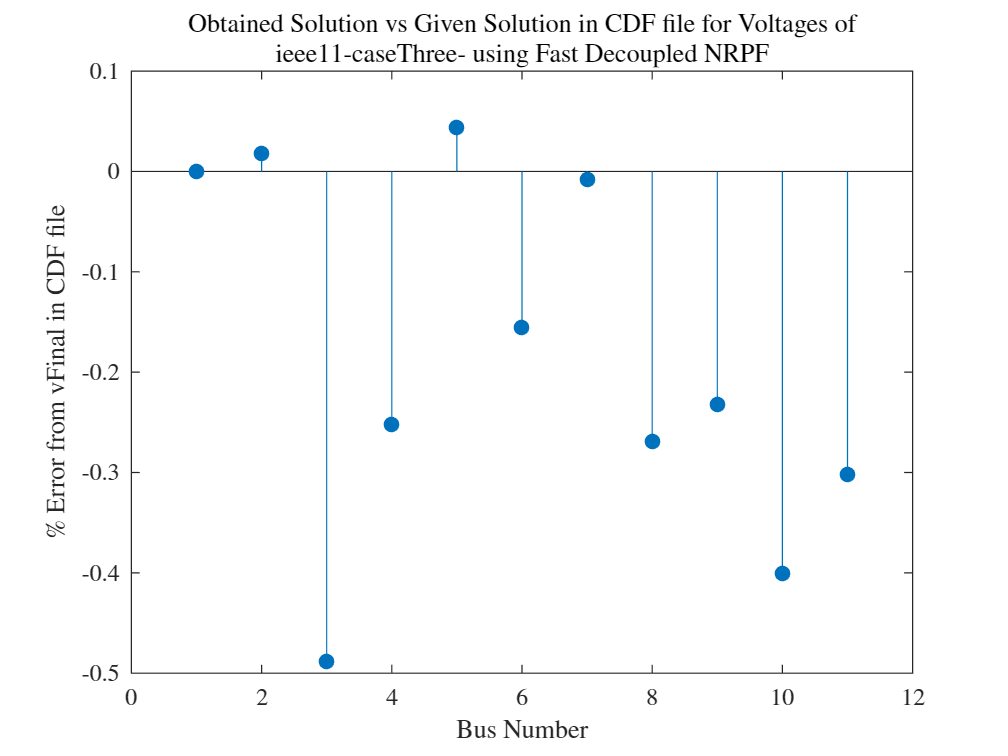

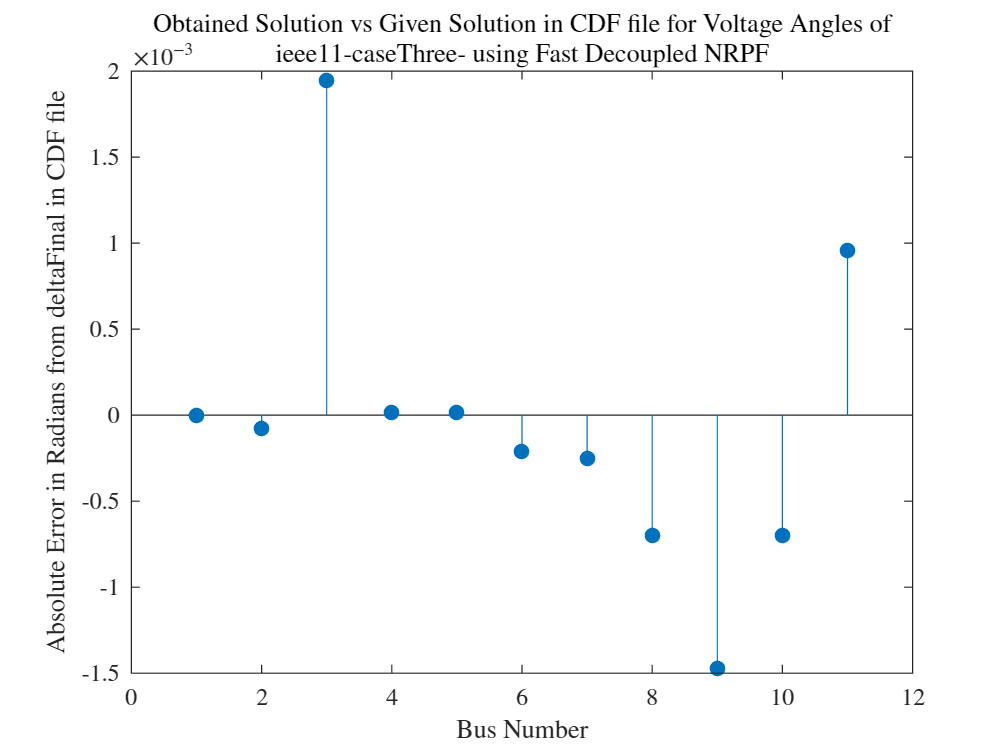

plotPowerFlowResults(showPlots, useSparseDSA, V, busData, systemName, powerFlowMethod, delta);

### Economic Dispatch and Optimal Power Flow Calculations:

if includeOPFScenarios && strcmp(systemName, 'ieee14') && ~useSparseDSA
    runOPFScenarios(busData, P, Q, V, delta, N, ybus, BMatrix, E, nPQ, nPV, listOfPQBuses, listOfNonSlackBuses, powerFlowMethod, MVAb, showOPFFormulae, showOPFValues, printPowerFlowConvergenceMessages)
end
toc;

Elapsed time is 2.536898 seconds.


# Have a nice day! 

In case you encounter a Java Heap Memory error, delete the above gif, or go to `Preferences->General->Java Heap Memory` and increase the allocated size.